%% Symbolic 6DoF Rocket Model 
clear; clc;

## ------------------ PARAMETERS ------------------

% --- Geometry / environment ---
g0   = 9.81;        % m/s^2
rho0 = 1.225;       % kg/m^3 (sea level)
S    = 0.010;       % m^2  reference area
d    = 0.10;        % m    reference diameter

% --- Mass / inertia ---
m  = 1.20;          % kg
Ix = 0.005;         % kg*m^2
Iy = 0.020;         % kg*m^2 
Iz = 0.020;         % kg*m^2

% --- Aerodynamic force coeffs ---
CA0       = 0.093292905;   % axial (drag-like)
CA_kalpha = 0.0593605;   % axial vs alpha
CA_kbeta  = 0.0593605;   % axial vs beta

% --- Moment coeffs ---
Cl_delta = 0.229;    % roll control effectiveness
Clp      = -10;     % roll damping
Cm_alpha = 2.6130694;    % pitch stability derivative
Cm_delta = 2.7716625;    % pitch control effectiveness
Cmq      = -24.89;     % pitch damping
Cn_beta  = 2.6130694;     % yaw stability derivative
Cn_delta = 2.7716625;     % yaw control effectiveness
Cnr      = -24.89;     % yaw damping

CY_beta = -2.0577392;
CY_zeta = -0.6508215;

CZ_alpha = -2.0577392;
CZ_eta = -0.6508215;


% --- Reference points ---
xcm  = 0.60;        % m 
xref = 0.5;        % m 

% --- Simplified propulsion  ---
Fp = 0;             % N 

% --- Avoid Singularities ---
epsN = 1e-6;

## ------------------ SYMBOLS (states + inputs) ------------------

% Inputs 
syms delta_eta delta_zeta delta_r real
u_in = [delta_eta; delta_zeta; delta_r];

% States 
syms u_b v_b w_b real
syms p q r real
syms phi theta psi real


x = [u_b; v_b; w_b; p; q; r; phi; theta; psi]

$$x = \left(\begin{array}{c} u_{b}\\ v_{b}\\ w_{b}\\ p\\ q\\ r\\ \varphi \\ \theta \\ \psi \end{array}\right)$$

## ------------------ DERIVED QUANTITIES ------------------

V = sqrt(u_b^2 + v_b^2 + w_b^2+ 1e-9^2) ;  % avoid div0
alpha = atan2(w_b,u_b);
beta  = asin(v_b / V); 
alpha_total = atan2(sqrt(v_b^2 + w_b^2 +1e-9^2), u_b);   

% Dynamic pressure q = 1/2 p V^2 for moments
Qdyn = 0.5*rho0*V^2;

## ------------------ AERO COEFFICIENT MODELS ------------------

CA = CA0 + CA_kalpha*alpha + CA_kbeta*beta;
CN = CY_beta*beta + CY_zeta*delta_zeta + CZ_alpha*alpha + CZ_eta*delta_eta;

% CN split into y/z components 
CNy = CN * (-v_b / sqrt(v_b^2 + w_b^2 + epsN^2));
CNz = CN * ( -w_b   / sqrt(v_b^2 + w_b^2 + epsN^2));

% Build direct force coefficiants
%CY = CY_beta*beta + CY_zeta*delta_zeta;
%CZ = CZ_alpha*alpha + CZ_eta*delta_eta;


## ------------------ FORCES ------------------

% Aerodynamic forces 
FAxb = -0.5*rho0*V^2 * CA  * S;
FAyb =  0.5*rho0*V^2 * CNy * S;
FAzb =  0.5*rho0*V^2 * CNz * S;

% Propulsion forces (simplified: thrust along +x_body)
FPxb = Fp; FPyb = sym(0); FPzb = sym(0);

% Gravity: Earth->Body transform using Euler angles 
cph = cos(phi);   sph = sin(phi);
cth = cos(theta); sth = sin(theta);
cps = cos(psi);   sps = sin(psi);

Te_b = [ cth*cps,  sph*sth*cps - cph*sps,  cph*sth*cps + sph*sps;
         cth*sps,  sph*sth*sps + cph*cps,  cph*sth*sps - sph*cps;
         -sth,     sph*cth,               cph*cth ];
Tb_e = Te_b.'; % inverse rotation

Fg_e = [m*g0; 0; 0];
Fg_b = Tb_e * Fg_e;
Fgxb = Fg_b(1); Fgyb = Fg_b(2); Fgzb = Fg_b(3);

## ------------------ TRANSLATIONAL DYNAMICS (body axes) -------------

udot = (FAxb + FPxb + Fgxb)/m - ( q*w_b - r*v_b );

vdot = (FAyb + FPyb + Fgyb)/m - ( r*u_b - p*w_b );

wdot = (FAzb + FPzb + Fgzb)/m - ( p*v_b - q*u_b );


## ------------------ MOMENTS ------------------

% Roll moment coefficient 
Cl = Cl_delta*delta_r + (d/(2*V))*Clp*p;

% Pitch & yaw moment coefficients
Cmref = Cm_alpha*alpha + Cm_delta*delta_eta;
Cnref = Cn_beta *beta  + Cn_delta*delta_zeta;

Cm = Cmref - CNz*((xcm-xref)/d) + (d/(2*V))*(Cmq + Cm_alpha)*q;
Cn = Cnref - CNy*((xcm-xref)/d) + (d/(2*V))*(Cnr + Cn_beta )*r;

% Aerodynamic moments
LA = Qdyn * Cl * S * d;
MA = Qdyn * Cm * S * d;
NA = Qdyn * Cn * S * d;

% Propulsion moments (set 0 for now)
Lp = sym(0); Mp = sym(0); Np = sym(0);

## ------------------ ROTATIONAL DYNAMICS ------------------

pdot = (LA + Lp - q*r*(Iz - Iy)) / Ix;

qdot = (MA + Mp - r*p*(Ix - Iz)) / Iy;

rdot = (NA + Np - p*q*(Iy - Ix)) / Iz;


## ------------------ EULER ANGLE RATES ------------------

phidot   = p + (q*sin(phi) + r*cos(phi))*tan(theta);
thetadot = q*cos(phi) - r*sin(phi);
psidot   = (q*sin(phi) + r*cos(phi))/cos(theta);

## ------------------ Assemble f(x,u) ------------------

f = [udot; vdot; wdot; pdot; qdot; rdot; phidot; thetadot; psidot];



## ------------------ Calculate A ------------------

A = jacobian(f,x)

A1 = subs(A,[delta_eta,delta_r,delta_zeta,p,phi,q,r,theta,v_b,w_b,u_b,psi],[0,0,0,0,0,0,0,0,0,0,60,0]);
A1 = double(A1)

A1 =    -0.0571   -0.0182   -0.0182         0         0         0         0         0         0
         0         0         0         0         0  -60.0000         0         0   -9.8100
         0         0         0         0   60.0000         0         0    9.8100         0
         0         0         0   -3.6750         0         0         0         0         0
         0         0    4.8015         0   -2.0467         0         0         0         0
         0    4.8015         0         0         0   -2.0467         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0


## ------------------ Calculate B ------------------

B = jacobian(f,u_in);
B1 = subs(B,[v_b,w_b,u_b],[0,0,60]);
B1 = double(B1)

B1 =          0         0         0
         0         0         0
         0         0         0
         0         0  100.9890
  305.5758         0         0
         0  305.5758         0
         0         0         0
         0         0         0
         0         0         0


## ------------------ Controllability ------------------

eigA1 = eig(A1)

eigA1 =   -0.0571 + 0.0000i
  -0.9415 +16.9380i
  -0.9415 -16.9380i
  -0.1637 + 0.0000i
 -17.9501 + 0.0000i
  16.0667 + 0.0000i
  -0.1633 + 0.0000i
   0.0000 + 0.0000i
  -3.6750 + 0.0000i


ctrlrank = rank(ctrb(A1,B1))

ctrlrank = 9


% Remove the uncontrollable state u
A1 = A1(2:9, 2:9);
B1 = B1(2:9, :);

## ------------------ LQR-Development ------------------


% --- Bryson rule: max acceptable deviations ---
xmax = [5;   5;   5;   5;   5;   deg2rad(20); deg2rad(20); deg2rad(20)];
umax = [deg2rad(20); deg2rad(20); deg2rad(20)];

Q = diag(1./(xmax.^2));
R = diag(1./(umax.^2));

% emphasize attitude + rates more than velocities
Q(3:5,3:5) = 10*Q(3:5,3:5);      % p,q,r
Q(6:8,6:8) = 100*Q(6:8,6:8);      % phi,theta,psi

% --- LQR gain ---
[K1,S,e] = lqr(A1,B1,Q,R);
disp('K ='); disp(K1);

K =
    0.0000    0.0873    0.0000    0.3487    0.0000    0.0000    6.6122    0.0000
   -0.0558    0.0000   -0.0000    0.0000    0.3309   -0.0000   -0.0000    6.6109
   -0.0000    0.0000    0.4617   -0.0000   -0.0000   10.0000   -0.0000   -0.0000



disp('Closed-loop eigenvalues ='); disp(e);

Closed-loop eigenvalues =
  -0.0645 + 0.0000i
  -0.0645 + 0.0000i
 -25.1514 +19.4242i
 -25.1514 -19.4242i
 -51.5510 +25.8452i
 -51.5510 -25.8452i
 -54.2736 +19.4913i
 -54.2736 -19.4913i




%figure
%plot(real(e), imag(e), 'rx', 'MarkerSize',8, 'LineWidth',2)
%grid on
%axis equal
%xlabel('Re')
%ylabel('Im')
%title('Closed-loop poles')


## ----------------- Observability ------------------

g = [
    udot;
    vdot;
    wdot;
    p;
    q;
    r;
    phi
    ]

$$g = \begin{array}{l} \left(\begin{array}{c} \frac{981\,\cos\left(\psi \right)\,\cos\left(\theta \right)}{100}-\frac{\left(\frac{4277374810888421\,\text{atan2}\left(w_{b},u_{b}\right)}{72057594037927936}+\frac{4277374810888421\,\sigma_{4}}{72057594037927936}+\frac{6722462275108977}{72057594037927936}\right)\,\sigma_{1}}{120}-q\,w_{b}+r\,v_{b}\\ p\,w_{b}-\frac{981\,\cos\left(\varphi \right)\,\sin\left(\psi \right)}{100}-r\,u_{b}+\frac{981\,\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{100}+\frac{v_{b}\,\sigma_{1}\,\sigma_{3}}{\sigma_{2}}\\ \frac{981\,\sin\left(\varphi \right)\,\sin\left(\psi \right)}{100}-p\,v_{b}+q\,u_{b}+\frac{981\,\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{100}+\frac{w_{b}\,\sigma_{1}\,\sigma_{3}}{\sigma_{2}}\\ p\\ q\\ r\\ \varphi \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{49\,{u_{b}}^{2}}{80}+\frac{49\,{v_{b}}^{2}}{80}+\frac{49\,{w_{b}}^{2}}{80}+\frac{49}{80000000000000000000}\\ \sigma_{2}=120\,\sqrt{{v_{b}}^{2}+{w_{b}}^{2}+\frac{1}{1000000000000}}\\ \sigma_{3}=\frac{5862078929769415\,\delta_{\eta }}{9007199254740992}+\frac{5862078929769415\,\delta_{\zeta }}{9007199254740992}+\frac{4633616747172831\,\text{atan2}\left(w_{b},u_{b}\right)}{2251799813685248}+\frac{4633616747172831\,\sigma_{4}}{2251799813685248}\\ \sigma_{4}=\mathrm{asin}\left(\frac{v_{b}}{\sqrt{{u_{b}}^{2}+{v_{b}}^{2}+{w_{b}}^{2}+\frac{1}{1000000000000000000}}}\right) \end{array}$$


C= jacobian(g,x)

C1 = subs(C,[delta_eta,delta_zeta,p,phi,psi,q,r,theta,u_b,v_b,w_b],[0,0,0,0,0,0,0,0,100,0,0]);

C1 = double(C1);
C1 = C1(:, 2:9);

rank(obsv(A1,C1))

ans = 8

## ----------------- Calculate scheduled A,B,C & K ------------------

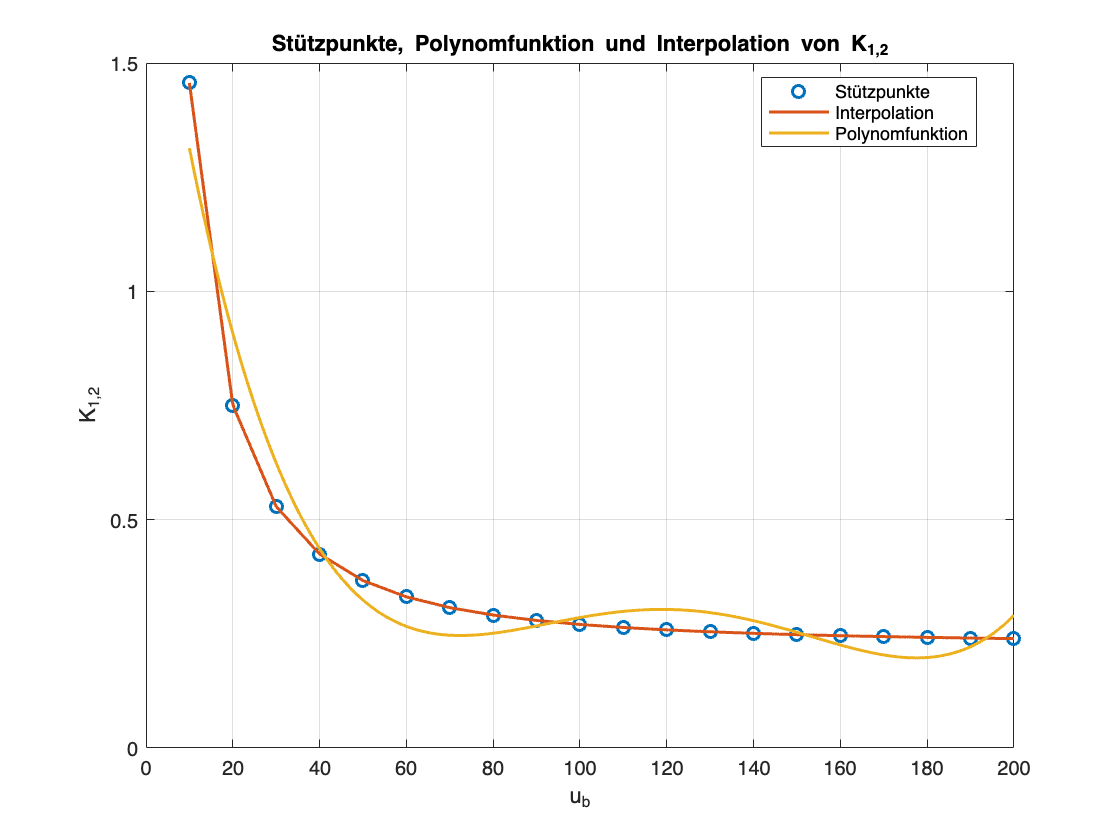

A = subs(A,[delta_eta,delta_r,delta_zeta,p,phi,q,r,theta,v_b,w_b,psi],[0,0,0,0,0,0,0,0,0,0,0]);
B = subs(B,[v_b,w_b],[0,0]);
C = subs(C,[delta_eta,delta_zeta,p,phi,psi,q,r,theta,v_b,w_b],[0,0,0,0,0,0,0,0,0,0]);

u_values = 10:10:200;
idx = 1;

A_all = cell(1,length(u_values));
B_all = cell(1,length(u_values));
C_all = cell(1,length(u_values));
K_all = cell(1,length(u_values));

% Calculate A,B,C and K for each step
for ub_val = u_values
    A_all{idx} = subs(A,u_b,ub_val);
    A_all{idx} = double(A_all{idx});
    A_all{idx} = A_all{idx}(2:9, 2:9);

    B_all{idx} = subs(B,u_b,ub_val);
    B_all{idx} = double(B_all{idx});
    B_all{idx} = B_all{idx}(2:9, :);

    C_all{idx} = subs(C,u_b,ub_val);
    C_all{idx} = double(C_all{idx});
    C_all{idx} = C_all{idx}(:, 2:9);

    K_all{idx} = lqr(A_all{idx}, B_all{idx}, Q, R);

    idx = idx + 1;
end

% Pack K Matrix into 3D-Array
[m,n] = size(K_all{1});
N = length(u_values);

K_array = zeros(m,n,N);

for k = 1:N
    K_array(:,:,k) = K_all{k};
end

% Fit polynoms
poly_order = 4;
P = cell(m,n);

K_fun = cell(m,n);

for i = 1:m
    for j = 1:n
        kij_values = squeeze(K_array(i,j,:));
        P{i,j} = polyfit(u_values, kij_values.', poly_order);
        K_fun{i,j} = griddedInterpolant(u_values, kij_values, 'linear');
    end
end

ub_val = 50;
K_eval = zeros(3,8);

for i = 1:m
    for j = 1:n
        %K_eval(i,j) = polyval(P{i,j}, ub_val);
        K_eval(i,j) = K_fun{i,j}(ub_val);
    end
end

% Stützpunkte von k(1,2) auslesen
k12_values = squeeze(K_array(2,5,:));

% Fein aufgelöste u-Werte für die Polynomkurve
u_fine = linspace(min(u_values), max(u_values), 500);

% Polynom auswerten
k12_pol = polyval(P{2,5}, u_fine);
k12_int = K_fun{2,5}(u_fine);
% Plot
figure('WindowStyle','normal')
plot(u_values, k12_values, 'o', 'LineWidth', 1.5, 'MarkerSize', 6);
hold on;
plot(u_fine, k12_int, '-', 'LineWidth', 1.5);
plot(u_fine, k12_pol, '-', 'LineWidth', 1.5);
grid on;

xlabel('u_b');
ylabel('K_{1,2}');
title('Stützpunkte, Polynomfunktion und Interpolation von K_{1,2}');
legend('Stützpunkte', 'Interpolation','Polynomfunktion', 'Location', 'best');